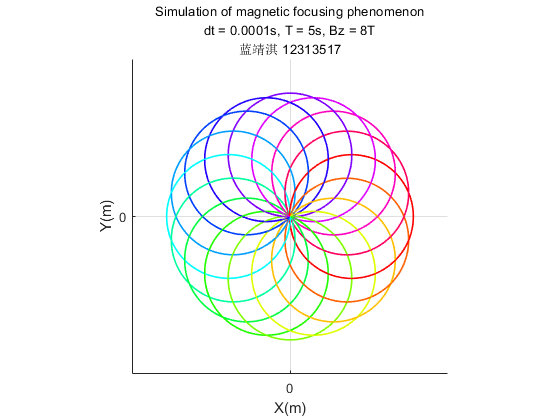

%% 磁聚焦仿真通用代码（修改参数即可生成对应图）
% ====================== 配置参数（根据图的要求修改） ======================
m = 0.02;           % 粒子质量（固定）
q = 1.6e-2;         % 粒子电荷量（固定）
dt = 0.0001;          % 时间步长（需修改：如0.01、0.001、0.0001）
T = 5;              % 总仿真时间（需修改：如5、10、20）
Bz = 8;             % 磁场强度（需修改：如8、20、200）
% =========================================================================

t = 0:dt:T;                     % 时间数组
num_particles = 16;             % 粒子数量（固定为16）

% 初始化速度、位置数组
vx = zeros(num_particles, length(t));
vy = zeros(num_particles, length(t));
vz = zeros(num_particles, length(t));
rx = zeros(num_particles, length(t));
ry = zeros(num_particles, length(t));
rz = zeros(num_particles, length(t));

% 初始条件（固定：z向速度10，xy向速度圆周分布）
for k = 0:num_particles-1
    vz(k+1,1) = 10;                      % 初始z向速度
    vx(k+1,1) = 0.1 * sin(k*pi/8);       % 初始x向速度
    vy(k+1,1) = 0.1 * cos(k*pi/8);       % 初始y向速度
    rx(k+1,1) = 0; ry(k+1,1) = 0; rz(k+1,1) = 0; % 初始位置
end

% 欧拉法求解运动方程
for i = 1:length(t)-1
    for k = 1:num_particles
        % 洛伦兹力（无电场，E=0）
        Fx = q * (vy(k,i)*Bz - vz(k,i)*0); % By=0
        Fy = q * (vz(k,i)*0 - vx(k,i)*Bz); % Bx=0
        Fz = q * (vx(k,i)*0 - vy(k,i)*0); % Bx=By=0
        
        % 加速度
        ax = Fx/m; ay = Fy/m; az = Fz/m;
        
        % 更新速度、位置
        vx(k,i+1) = vx(k,i) + ax*dt;
        vy(k,i+1) = vy(k,i) + ay*dt;
        vz(k,i+1) = vz(k,i) + az*dt;
        rx(k,i+1) = rx(k,i) + vx(k,i)*dt;
        ry(k,i+1) = ry(k,i) + vy(k,i)*dt;
        rz(k,i+1) = rz(k,i) + vz(k,i)*dt;
    end
end

%% 绘图（匹配文档中的视图/标题）
figure('Name', ['图_' num2str(1)]);
hold on; grid on;
pbaspect([1 1 2]); % 坐标轴比例（匹配文档）

% 标题：包含dt、T、Bz、姓名（替换为你的信息）
title(["Simulation of magnetic focusing phenomenon", ...
       "dt = " + dt + "s, T = " + T + "s, Bz = " + Bz + "T", ...
       "蓝靖淇 12313517"], "FontSize",10);

xlabel('X(m)'); ylabel('Y(m)'); zlabel('Z(m)');
xticks(-1:0.5:1); yticks(-1:0.5:1);

% 视图选择：3D视图（文档中大部分图）或2D视图（图10-12）
view(2); % 3D视图（图1-9）；若要2D视图（图10-12），改为view(2)

% 绘制16个粒子的轨迹（彩色区分）
colors = hsv(num_particles);
for k = 1:num_particles
    plot3(rx(k,:), ry(k,:), rz(k,:), 'Color', colors(k,:), 'LineWidth', 0.8);
end
hold off;